clear all;
close all;
clc;

f = 200; % Signal fundamental frequency of 200Hz.
fs= 5000; % Sampling frequency of 5kHz.
N = 5000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,5000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_supersition = sum(x, 1);
subplot(2,1,1);
stem(n, signal_supersition);
% stem(n*T, signal_supersition);
xlabel('n');
ylabel('x(n)');
title('Signal sampled at 5kHz in time domain');
% soundsc(signal_supersition);

fft_for_signal = fft(signal_supersition);
f = 0:4999;
subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal sampled at 5kHz in frequency domain');
hold off;
% Read the audio file into workspace.
[samples_of_the_filter, fs_of_filter] = audioread('telephoneIR.wav');

signal_interleave_with_zeros = zeros(1, 5000*22);
index = 1;
for i = 1:40000
    if mod(i, 22) == 1
        signal_interleave_with_zeros(i) = signal_supersition(index);
        index = index + 1;
    end
end

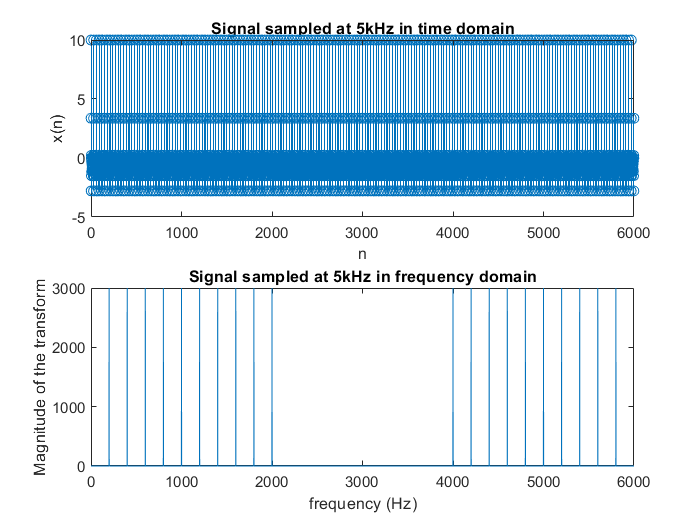

clear all;
close all;
clc;
f = 200; % Signal fundamental frequency of 200Hz.
fs= 6000; % Sampling frequency of 5kHz.
N = 6000; % Since duration of the signal is 1s, and fs=5kHz, we need 5000 samples.
n = 0:N-1;
T= 1/fs; % Sample period.
x = zeros(10,6000); % Matrix for the whole signal
for i = 1:10
    x(i,:) = cos(2*pi*i*f*n*T);
end

signal_supersition = sum(x, 1);
subplot(2,1,1);
stem(n, signal_supersition);
% stem(n*T, signal_supersition);
xlabel('n');
ylabel('x(n)');
title('Signal sampled at 5kHz in time domain');
% soundsc(signal_supersition);

fft_for_signal = fft(signal_supersition);
f = 0:5999;
subplot(2,1,2);
plot(f, abs(fft_for_signal));
xlabel('frequency (Hz)');
ylabel('Magnitude of the transform');
title('Signal sampled at 5kHz in frequency domain');
hold off;

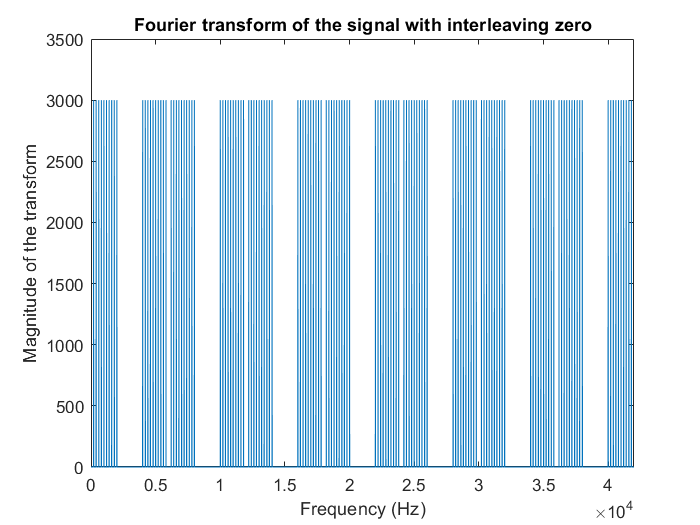

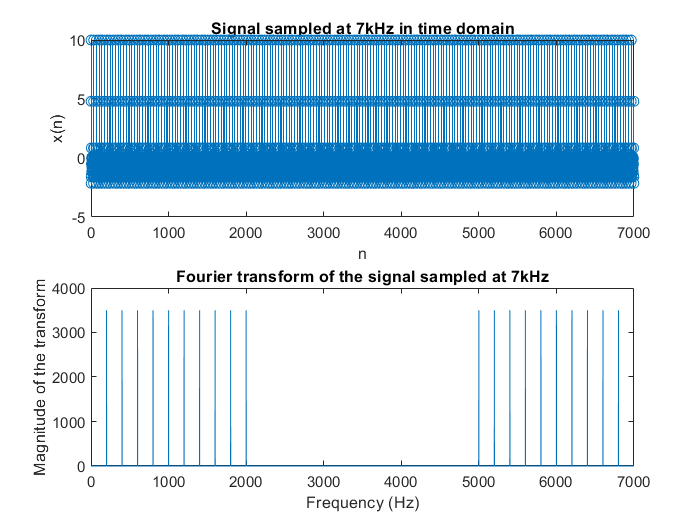

ans =    10.0000    4.8049   -2.1459   -1.6047    0.8533   -0.5000   -1.4271    0.0000   -0.0533   -1.1579   -0.5000    0.0698   -0.8337   -0.8196   -0.0000   -0.5000   -0.9799   -0.2058   -0.2058   -0.9799   -0.5000    0.0000   -0.8196   -0.8337    0.0698   -0.5000   -1.1579   -0.0533   -0.0000   -1.4271   -0.5000    0.8533   -1.6047   -2.1459    4.8049   10.0000    4.8049   -2.1459   -1.6047    0.8533   -0.5000   -1.4271   -0.0000   -0.0533   -1.1579   -0.5000    0.0698   -0.8337   -0.8196    0.0000



resample_by_factor_p_over_q(signal_supersition, 7, 6)

clear all;
close all;
clc;

load after_interleave_data.mat;
fft_data = fft(signal_interleave_with_zeros);
k = 0:175999;
plot(k, abs(fft_data))